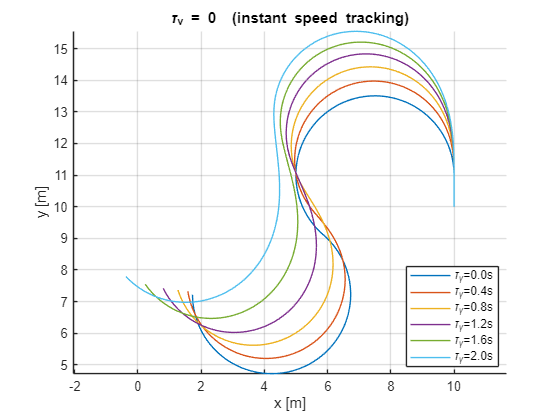

clear;
clc;

function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; 
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1);  % desired steering angle
    v_d     = u(2);  % desired velocity

    % Saturate desired inputs
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % treat zero lags as instantaneous tracking
    if tau_gamma == 0,  gamma = gamma_d;  dgamma = 0;  end
    if tau_v     == 0,  v     = v_d;      dv     = 0;  end

    % First-order dynamics for steering and velocity
    epsLag = 1e-12;                 % small positive number
    dgamma = (gamma_d - gamma)/(tau_gamma + epsLag);
    dv     = (v_d     - v    )/(tau_v     + epsLag);


    % Euler integration to update gamma and v
    gamma = gamma + dt * dgamma;
    v     = v + dt * dv;

    % Bicycle model kinematics
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration to update pose
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;

    % Saturate state vector
    x     = max(min(x, Qmax(1)), Qmin(1));
    y     = max(min(y, Qmax(2)), Qmin(2));
    theta = max(min(theta, Qmax(3)), Qmin(3));
    gamma = max(min(gamma, Qmax(4)), Qmin(4));
    v     = max(min(v, Qmax(5)), Qmin(5));

    % Pack next state
    q_next = [x; y; theta; gamma; v];
end

% ── vehicle, world, and integration parameters ─────────────────────────
global dt  DT                 % required by robot_bike_dyn.m
L          = 2.5;             % wheel‑base  [m]
gamma_max  = pi/4;            % ±45°
v_cmd      = 1.0;             % desired speed [m/s]
dt         = 0.01;            % integration Δt [s]
DT         = 0.1;             % not used here
T_total    = 21.0;            % 1 + 10 + 10  [s]
steps      = round(T_total/dt);
t          = (0:steps)*dt;

% Input limits & state limits (very loose so nothing clips)
umin  = [-gamma_max  -Inf];
umax  = [ gamma_max   Inf];
Qmin  = [-Inf -Inf -Inf  -gamma_max   0];
Qmax  = [ Inf  Inf  Inf   gamma_max   5];

% steering wheel function
gamma_d_profile = @(tk) ...
    ( tk <  1.0 ) .* 0               + ...
    ( tk >= 1.0  & tk < 11.0 ) .*  gamma_max + ...
    ( tk >= 11.0               ) .* (-gamma_max);

% list of lags
tau_g_list = 0 : 0.4 : 2;     % 0,0.4,…,2  (six values)

% 1.  τv = 0  (instantaneous speed tracking)
figure;  hold on;  grid on;  axis equal
title('\tau_v = 0  (instant speed tracking)'), xlabel('x [m]'), ylabel('y [m]')

for tau_g = tau_g_list
    % — initial state  [x y θ γ v]^T
    q = [10; 10; pi/2; 0; v_cmd];

    % — storage for plot
    trace = zeros(steps+1, 2);
    trace(1,:) = q(1:2).';

    for k = 1:steps
        tk = t(k);                          % current time
        gamma_d = gamma_d_profile(tk);      % desired steering
        u       = [gamma_d, v_cmd];         % input vector

        % call dynamics
        q = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax,...
                           L, tau_g, 0);
        trace(k+1,:) = q(1:2).';
    end
    plot(trace(:,1), trace(:,2), 'DisplayName', ...
        sprintf('\\tau_{\\gamma}=%.1fs', tau_g));
end
legend('Location','best')

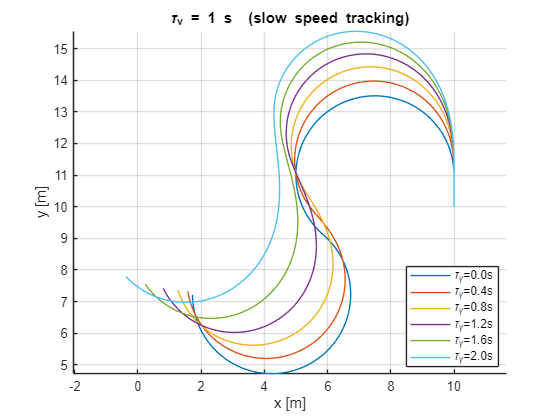


% 2.  τv = 1 s  (slow speed tracking)
figure;  hold on;  grid on;  axis equal
title('\tau_v = 1 s  (slow speed tracking)'), xlabel('x [m]'), ylabel('y [m]')

for tau_g = tau_g_list
    q     = [10; 10; pi/2; 0; v_cmd];
    trace = zeros(steps+1, 2);  trace(1,:) = q(1:2).';

    for k = 1:steps
        tk      = t(k);
        gamma_d = gamma_d_profile(tk);
        u       = [gamma_d, v_cmd];

        q = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax,...
                           L, tau_g, 1);   % τv = 1 s

        trace(k+1,:) = q(1:2).';
    end
    plot(trace(:,1), trace(:,2), 'DisplayName', ...
        sprintf('\\tau_{\\gamma}=%.1fs', tau_g));
end
legend('Location','best')